# E5

1. Dilatació i erosió

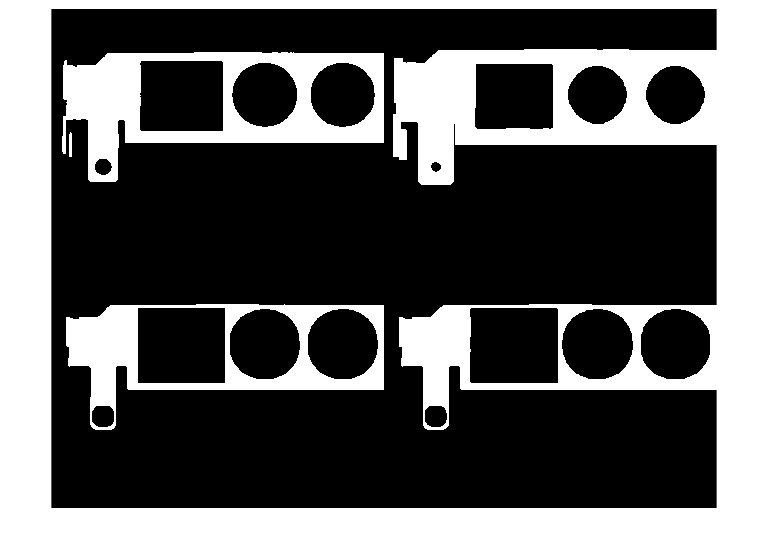

I = imread("Bracket1.tif");
BW = I < 128;
SE = ones(11,11);
% Dilatació
BWD = imdilate(BW,SE);

% Erosió
BWE = imerode(BW,SE);

% Test: erosió es una dilatació del background
BWT = not(imdilate(not(BW),SE));

montage({BW,BWD,BWE,BWT});

2. Residus

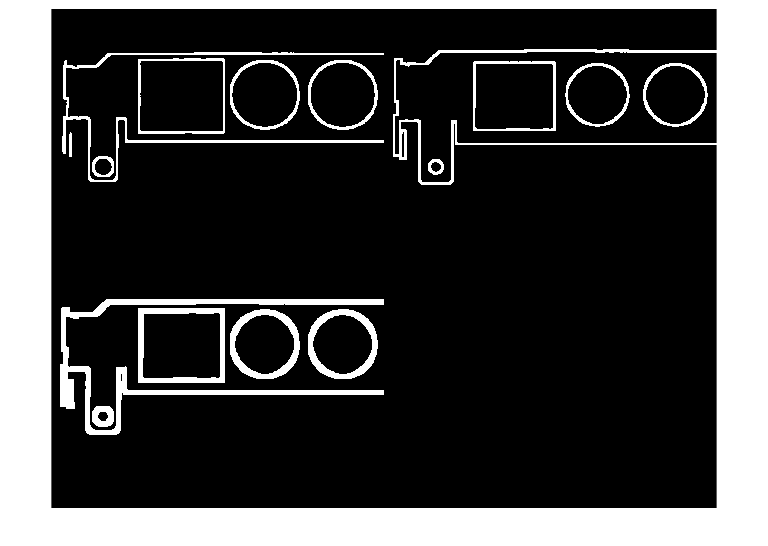

% Intern: imatge - erosió
RI = BW & not(BWE);

% Extern: dilatació - imatge
RE = BWD & not(BW);

% Tots dos: dilatació - erosió
RD = BWD & not(BWE);

% Laplacià: gradient extern - gradient intern
L = double(RE) - double(RI);

montage({RI,RE,RD});

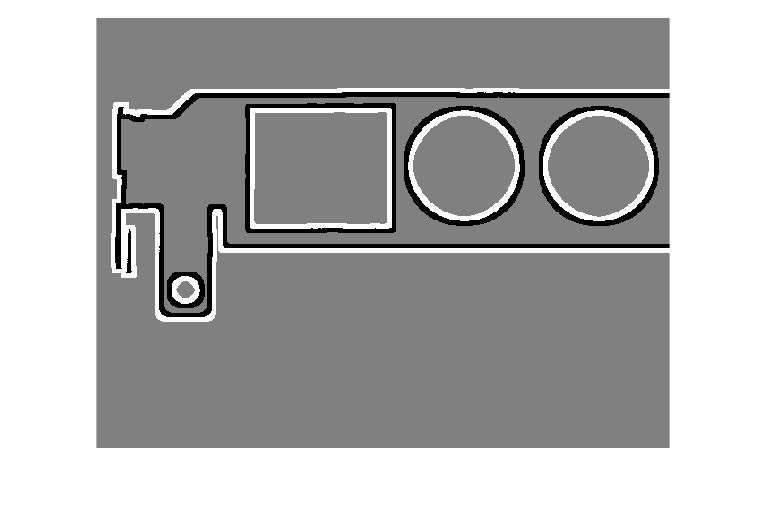


imshow(L, []);

3. Transformada de la distancia

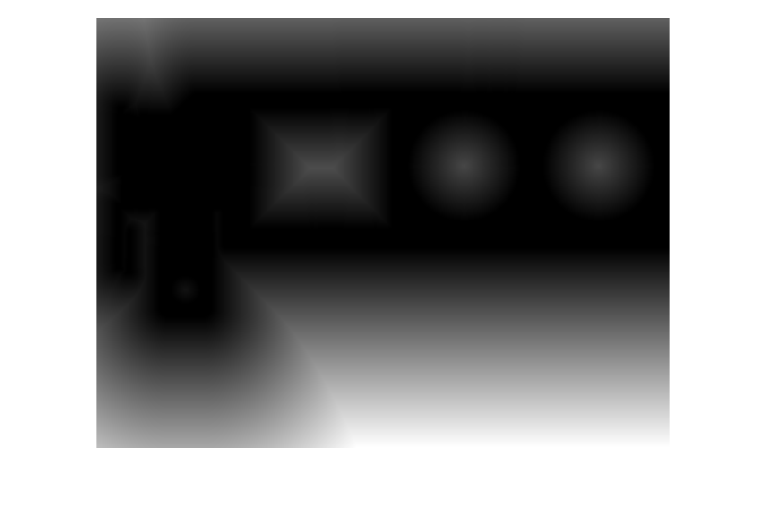

TD = bwdist(BW,"euclidean");
imshow(TD,[]);

4. Reconstrucció

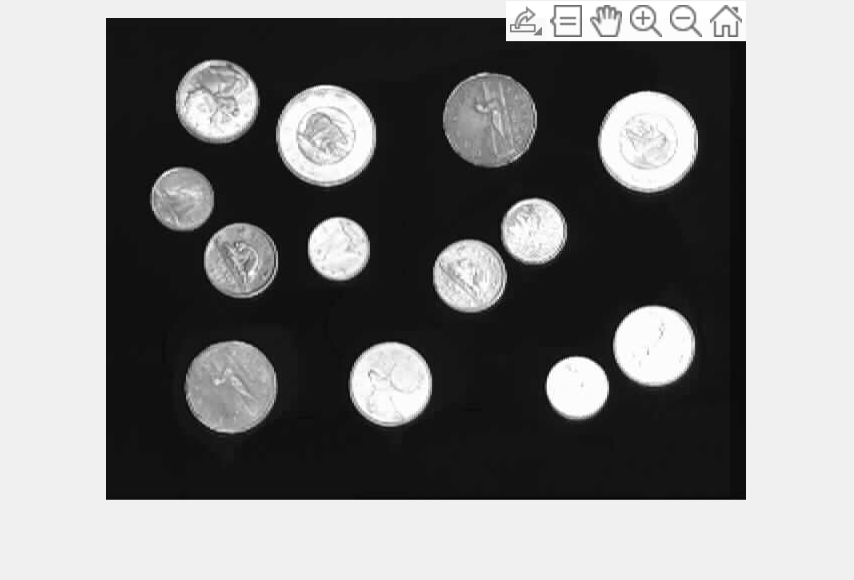

I = imread("money.tif");
BW = I > 128;
SE = ones(5,5);
imshow(I,[]);
[x y] = getpts;

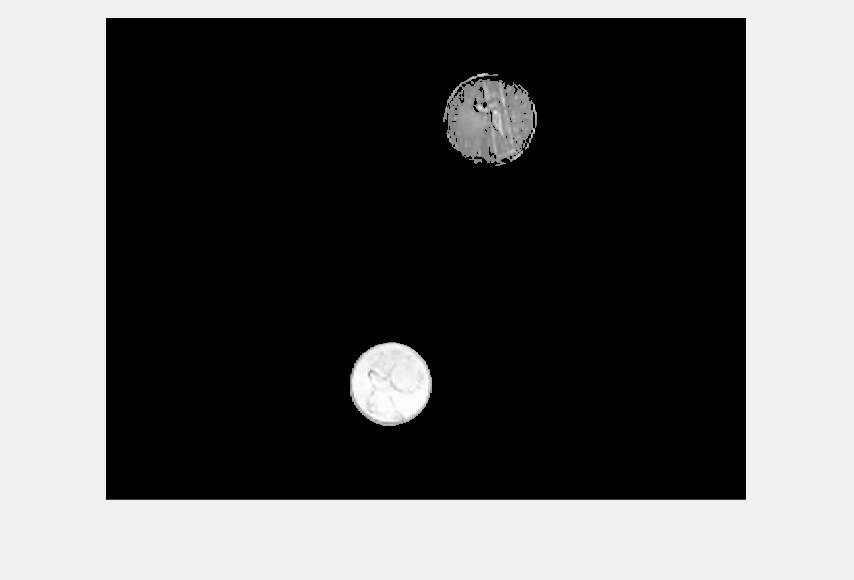

MARK = false(size(BW));
for i = 1:size(x)
    MARK(uint16(y(i)),uint16(x(i))) = 1;
end
REC = imreconstruct(MARK,BW);
% imshow(REC, []);
imshow(uint8(REC).*I,[]);

Exercici: eliminar objectes de les vores

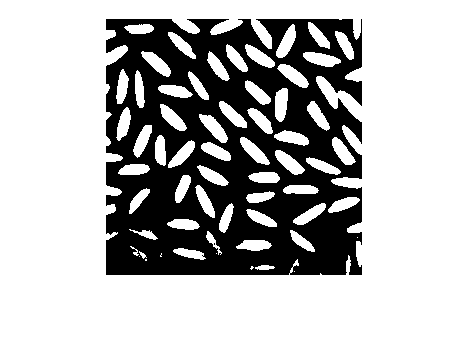

I = imread("arros.tif");
BW = I > 128;
SE = ones(5,5);
imshow(BW,[]);

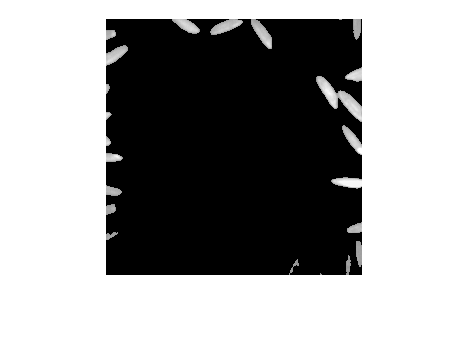


MARK = false(size(BW));

% vores de la imatge
MARK(1,:) = 1;
MARK(end,:) = 1;
MARK(:,1) = 1;
MARK(:,end) = 1;

REC = imreconstruct(MARK,BW);
imshow(uint8(REC).*I,[]);

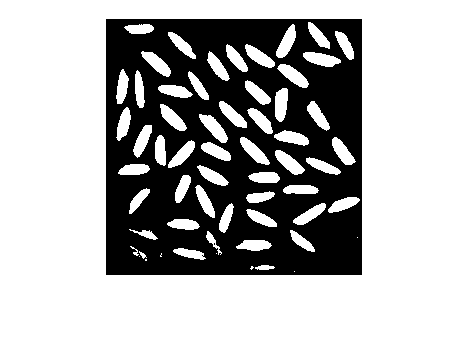


BWM = BW & not(REC);
imshow(BWM);

5. Close: dilatació + erosió

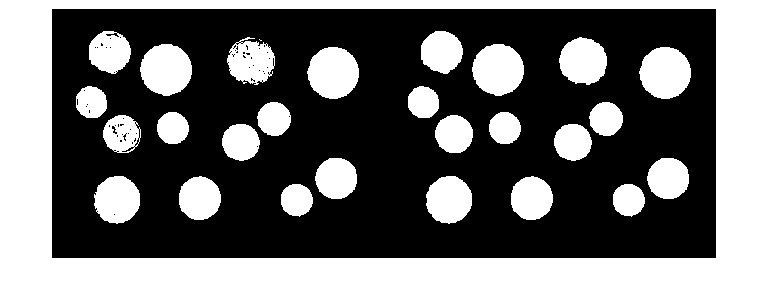

I = imread("money.tif");
BW = I > 128;
SE = ones(7,7);
BWC = imdilate(BW,SE);
BWC = imerode(BWC,SE); % close
montage({BW,BWC});

Exercici: comptar les dents d'una roda dentada

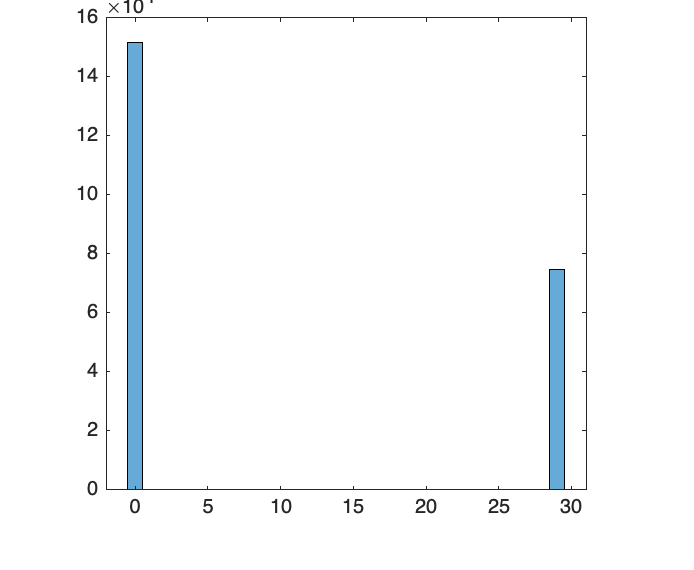

I = rgb2gray(imread("Wheel.bmp"));
histogram(I);

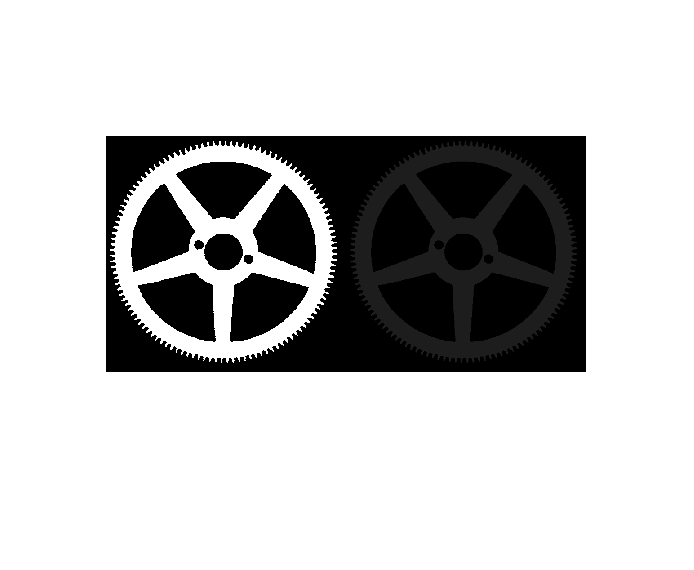

BW = I > 15;
montage({BW,I});

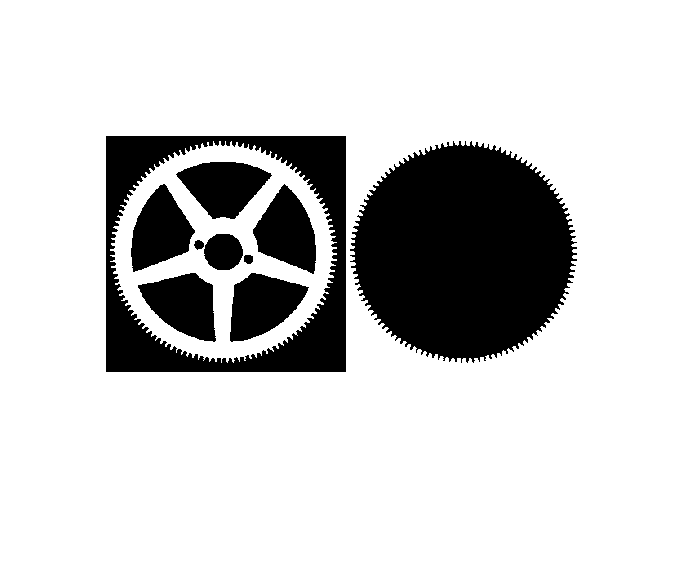


MARK = false(size(BW));

% vores de la imatge
MARK(1,:) = 1;
MARK(end,:) = 1;
MARK(:,1) = 1;
MARK(:,end) = 1;

REC = imreconstruct(MARK,not(BW));
montage({BW,REC});

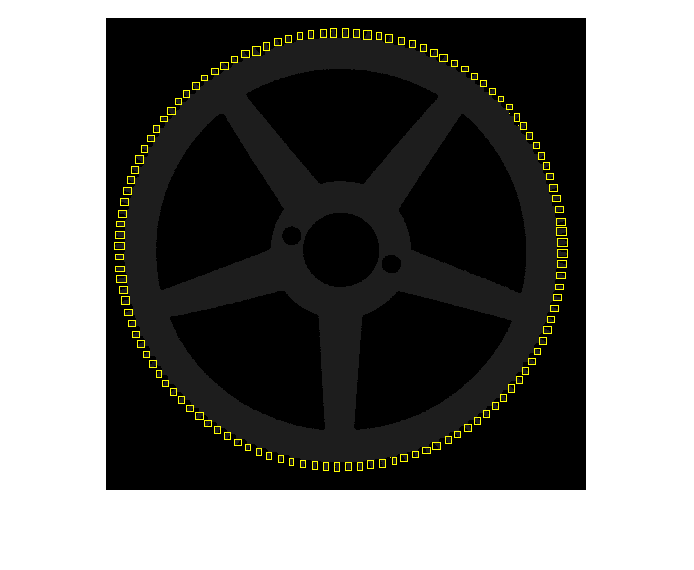

REC = not(REC);
O = imopen(REC, ones(10,10));
BWS = REC & not(O);
%imshow(REC);
%region props
RP = regionprops('table',BWS,'BoundingBox','Area');
RGB = insertShape(I,'rectangle',RP.BoundingBox);
imshow(RGB);

Exercici: entrar en un laberint

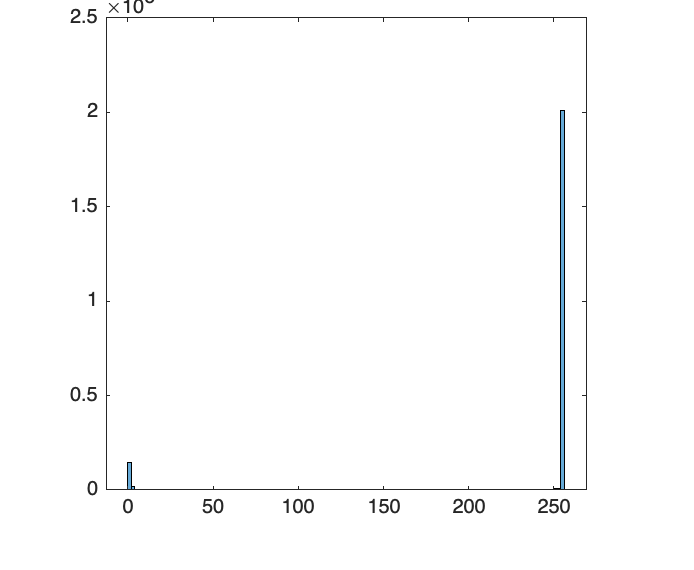

I = rgb2gray(imread("Laberint.png"));
histogram(I);

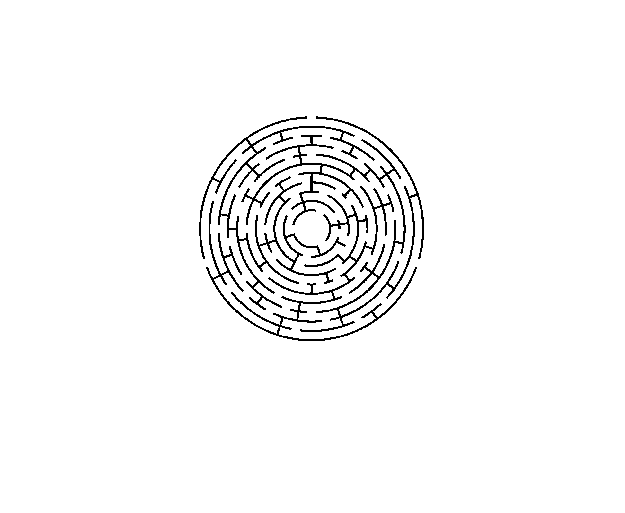


BW = I > 128;
montage({BW});

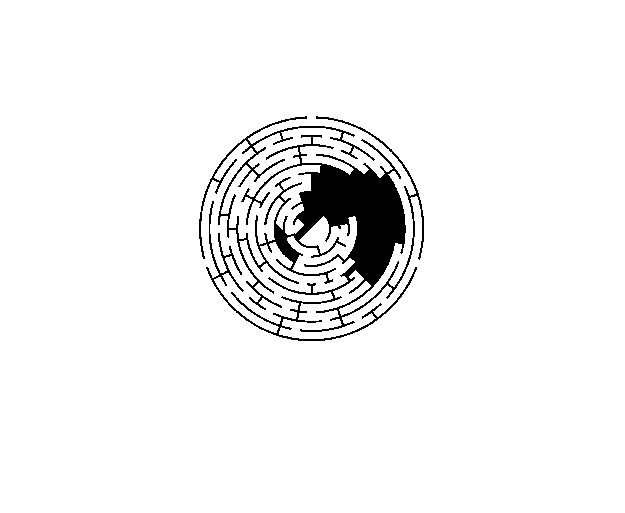

MARK = false(size(BW));
DT = zeros(size(BW));
MARK(1,1) = 1; % posició inicial de la partida
SE = [0 1 0; 1 1 1; 0 1 0];
[f c] = size(BW);
centre = [floor(f/2) floor(c/2)];

fi = false;
while(not(fi))
    MARK = imdilate(MARK,SE) & BW;
    %imshow(MARK);
    DT = DT + MARK;
    if MARK(centre(1),centre(2))
        fi = true;
    end
end

imshow(MARK);

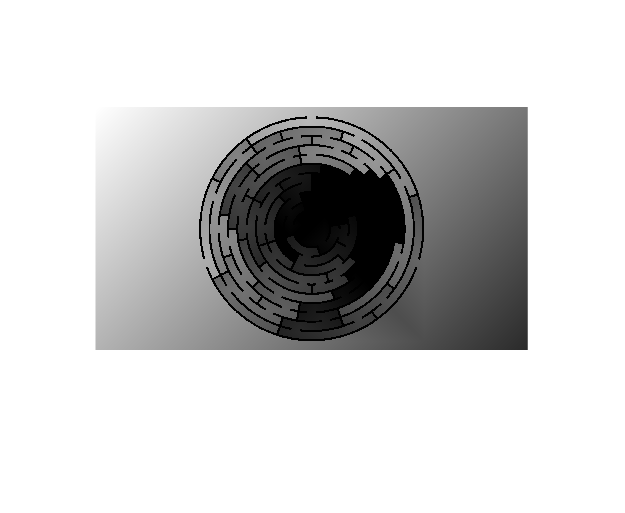

imshow(DT, []);